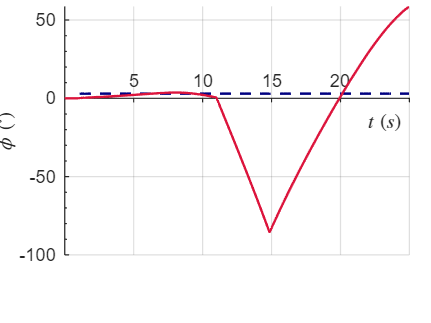

clear
clc


% 0 Controller value

Kp_a = -30;

Ki_a = -1;

Kp_b = -19;

Ki_b = -1;

Kp_c = 7;

Ki_c = 5;

% 1 Run model
open('Roll_Attitude_Hold.slx');
out = sim('Roll_Attitude_Hold.slx');

% 2 Extract time and signal data
t = out.phi.Time;
phi = out.phi.Data;
step = out.step.Data;

% 3 Compute step response characteristics

% Plot for verification
[ha, pos] = tight_subplot(1,1, ...   % Nh, Nw
                          [0.08 0.08], ...
                          [0.21 0.02], ...    % marg_h [bottom top]
                          [0.15 0.05]);       % marg_w [left  right]

ax = ha(1);            % handle to the only axes
axes(ax);              % activate it

plot(t, step .* 180 ./ pi, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5);
hold on
plot(t, phi .* 180 ./ pi, 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold off

set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

xlim([0 25]);
% ylim([0 3.5]);

xlabel('$t \; (s)$', 'Interpreter', 'latex');
ylabel('$\phi \; (^\circ)$', 'Interpreter', 'latex');


grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 400 300]);


% Compute step response characteristics
info = stepinfo(phi, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 7.6794
    TransientTime: 49.9208
     SettlingTime: 49.9209
      SettlingMin: -897.4573
      SettlingMax: -897.4573
        Overshoot: 0
       Undershoot: 0.1234
             Peak: 897.4573
         PeakTime: 50

